ZEP_st.name='ZEP'; 
ZEP_st.lat=78.91;
ZEP_st.lon=11.89;
ZEP_st.alt=475;
ZEP_st.env='P';
ZEP_st.footp='P';

ZEP_rdx=read_betsy('zep_2002_2017',ZEP_st.name);
%with all digit (long
ZEP_rd=read_betsy('zep_2002_2017_longformat',ZEP_st.name);
%problem NAN
ZEP_rd.Ba5_A11(ZEP_rd.Ba5_A11>40)=NaN;
ZEP_rd.Ba6_A11(ZEP_rd.Ba6_A11>40)=NaN;
ZEP_rd.Ba7_A11(ZEP_rd.Ba7_A11>40)=NaN;

%read neph from Dominic (Paul)
scat=table2timetable(NepdataZEP);
%problem: low data were probably deleted: not usable for me in this shape.
scat2=table2timetable(dfweightsnodetectionlimit);
scat2_d=retime(scat2,'daily',@nanmedian);

datevec(ZEP_rd.Time(1))

ans =         2002           1           2           0           0           0


datevec(ZEP_rd.Time(end))

ans =         2018           1           1           0           0           0


prctile(ZEP_rd.U_S11,[5 50 95])

ans =    296   300   304


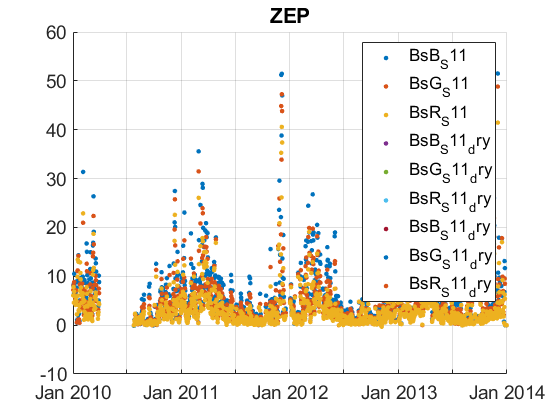

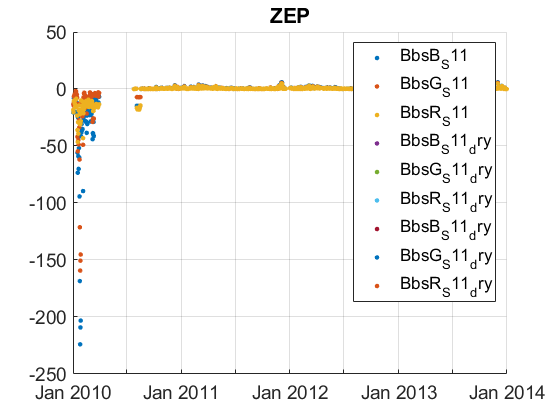

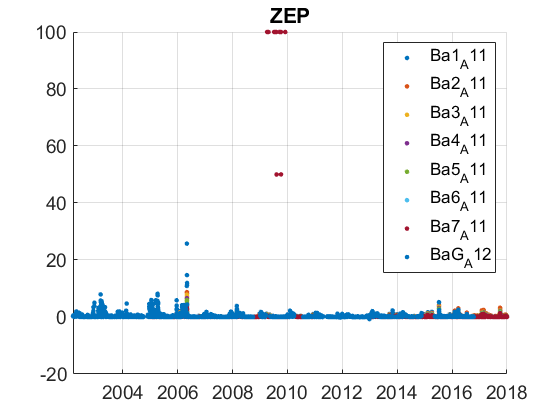

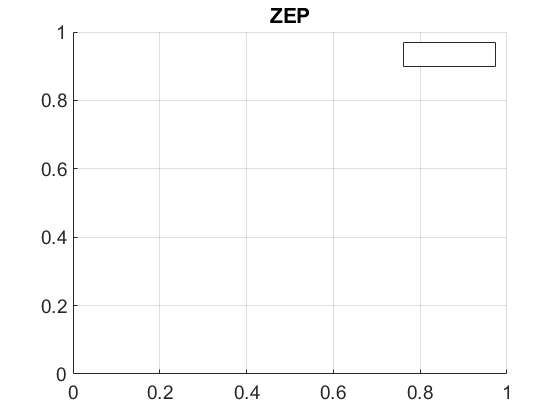

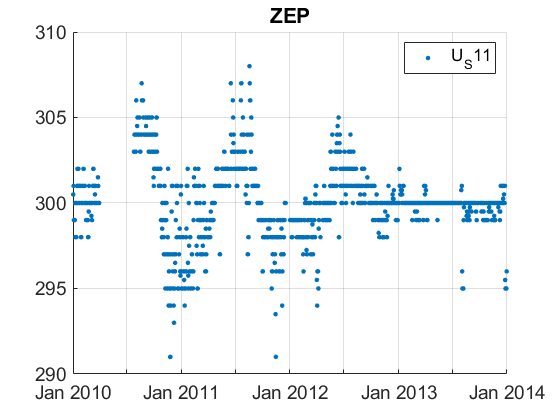

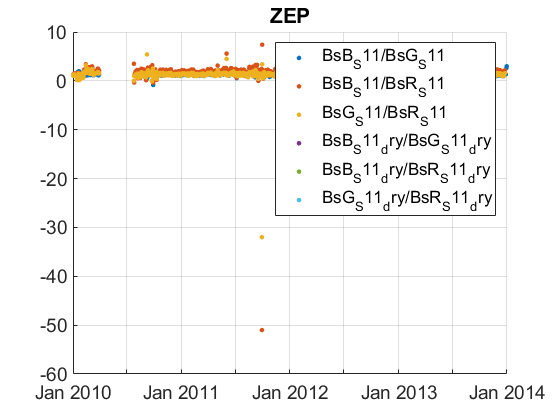

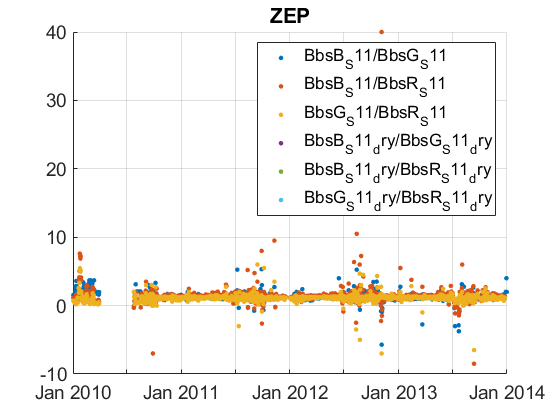

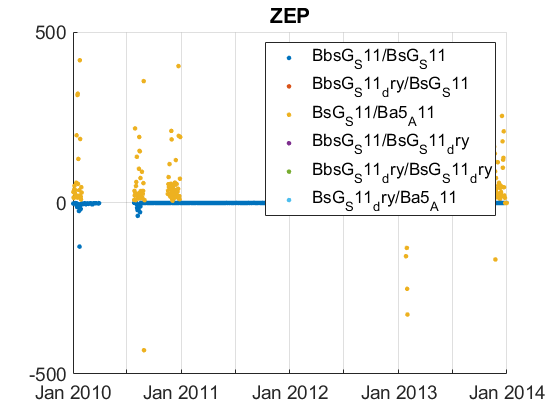

plotFigControl(ZEP_rd,ZEP_st.name);

plot(scat2.VarName1, scat2.scat450,'.b');
plot(scat2.VarName1, scat2.scat550,'.r');
plot(scat2_d.VarName1, scat2_d.scat550,'.r');
figure;
plot(ZEP_rd.Time,ZEP_rd.Ba3_A11./ZEP_rd.BaG_A12);
ind=ZEP_rd.Ba3_A11>0.09;
hold on;
plot(ZEP_rd.Time(ind),ZEP_rd.Ba3_A11(ind)./ZEP_rd.BaG_A12(ind),'.r');
figure;
plot(ZEP_rd.Ba3_A11(ind& ZEP_rd.Time>datetime('2007-01-01')),ZEP_rd.BaG_A12(ind& ZEP_rd.Time>datetime('2007-01-01')),'.');
figure;
plot(ZEP_rd.Time,ZEP_rd.Ba3_A11-ZEP_rd.BaG_A12,'.');

%linear fit of the ratio after 2007 gives a slope=1.2*x+0.53
med_ratio=nanmedian(ZEP_rd.Ba3_A11(ind& ZEP_rd.Time>datetime('2007-01-01'))./ZEP_rd.BaG_A12(ind& ZEP_rd.Time>datetime('2007-01-01')))
med_sub=nanmedian(ZEP_rd.Ba3_A11(ind& ZEP_rd.Time>datetime('2007-01-01'))-ZEP_rd.BaG_A12(ind& ZEP_rd.Time>datetime('2007-01-01')))

%it means tath A11 is lower than A12
med_ratio2=nanmedian((ZEP_rd.Ba3_A11(ind& ZEP_rd.Time>datetime('2007-01-01'))+0.075)./ZEP_rd.BaG_A12(ind& ZEP_rd.Time>datetime('2007-01-01')))
%result==1.000 !
mean_ratio2=nanmean((ZEP_rd.Ba3_A11(ind& ZEP_rd.Time>datetime('2007-01-01'))+0.075)./ZEP_rd.BaG_A12(ind& ZEP_rd.Time>datetime('2007-01-01')))
%test on figure with abs
hold on;
plot(ZEP_rd.Time,ZEP_rd.BaG_A12-0.075,'.r','MarkerSize',10);

% this leads to too low A12. Test with difference of all data
med_sub_all=nanmedian(ZEP_rd.Ba3_A11( ZEP_rd.Time>datetime('2007-01-01'))-ZEP_rd.BaG_A12( ZEP_rd.Time>datetime('2007-01-01')))
med_ratio3=nanmedian((ZEP_rd.Ba3_A11(ZEP_rd.Time>datetime('2007-01-01'))+0.035)./ZEP_rd.BaG_A12(ZEP_rd.Time>datetime('2007-01-01')))

plot(ZEP_rd.Time,ZEP_rd.BaG_A12-0.035,'.g','MarkerSize',10);
%NOT POSSIBLE TO HOMOGENISE EASILY, TAKE JUST AE31

AE_x=table2timetable(zeppelin1hMartine);
AE_x=AE_x(3:end,:);
AE_x.Abs370(AE_x.Abs370>99999)=NaN;
AE_x.Abs470(AE_x.Abs470>99999)=NaN;
AE_x.Abs520(AE_x.Abs520>99999)=NaN;
AE_x.Abs590(AE_x.Abs590>99999)=NaN;
AE_x.Abs660(AE_x.Abs660>99999)=NaN;
AE_x.Abs880(AE_x.Abs880>99999)=NaN;
AE_x.Abs950(AE_x.Abs950>99999)=NaN;

AE_x_d=retime(AE_x,'daily',@nanmedian);

%add dominic scat to ZEP_rd
namesD=fieldnames(scat2_d);
c= startsWith(namesD,["AE";"w";"n"]);
ND=namesD(c);

scatD_totake=scat2_d;
for i=1:length(ND)
    scatD_totake.(ND{i})=[];
end

%data to take: Dominic + a dataset with Betsy 2013 added

ZEP_rd2=outerjoin(ZEP_rd,scatD_totake);
%name correctly Dominic data
ZEP_rd2.BsB_S12=ZEP_rd2.scat450;
ZEP_rd2.scat450=[];
ZEP_rd2.BsG_S12=ZEP_rd2.scat550;
ZEP_rd2.scat550=[];
ZEP_rd2.BsR_S12=ZEP_rd2.scat700;
ZEP_rd2.scat700=[];

ZEP_rd2.BbsB_S12=ZEP_rd2.bscat450;
ZEP_rd2.bscat450=[];
ZEP_rd2.BbsG_S12=ZEP_rd2.bscat550;
ZEP_rd2.bscat550=[];
ZEP_rd2.BbsR_S12=ZEP_rd2.bscat700;
ZEP_rd2.bscat700=[];

%one serie with Betsy 2013
%decalage d'une heure entre les 2 sets de données
PP1=timerange('2013-02-23','2013-09-19');
PP2=timerange('2013-02-22','2013-09-18');
ZEP_rd2.BsG_S13=ZEP_rd2.BsG_S12;
ZEP_rd2.BsG_S13(PP2)=ZEP_rd2.BsG_S11(PP1);
ZEP_rd2.BbsG_S13=ZEP_rd2.BbsG_S12;
ZEP_rd2.BbsG_S13(PP2)=ZEP_rd2.BbsG_S11(PP1);

ZEP_rd2.BsB_S13=ZEP_rd2.BsB_S12;
ZEP_rd2.BsB_S13(PP2)=ZEP_rd2.BsB_S11(PP1);
ZEP_rd2.BbsB_S13=ZEP_rd2.BbsB_S12;
ZEP_rd2.BbsB_S13(PP2)=ZEP_rd2.BbsB_S11(PP1);

ZEP_rd2.BsR_S13=ZEP_rd2.BsR_S12;
ZEP_rd2.BsR_S13(PP2)=ZEP_rd2.BsR_S11(PP1);
ZEP_rd2.BbsR_S13=ZEP_rd2.BbsR_S12;
ZEP_rd2.BbsR_S13(PP2)=ZEP_rd2.BbsR_S11(PP1);
%idem pour 2010, but backscattering is not good
PP3=timerange('2010-01-02','2010-03-30');
PP4=timerange('2010-01-01','2010-03-29');
ZEP_rd2.BsG_S13(PP4)=ZEP_rd2.BsG_S11(PP3);
ZEP_rd2.BsB_S13(PP4)=ZEP_rd2.BsB_S11(PP3)

ZEP_rd2 = 6805×35 timetable
            Time            P_S11    T_S11    U_S11    BbsB_S11    BbsG_S11    BbsR_S11    BsB_S11    BsG_S11    BsR_S11    Ba1_A11    Ba2_A11    Ba3_A11    Ba4_A11    Ba5_A11    Ba6_A11    Ba7_A11    BaG_A12    BbsB_S11_dry    BbsG_S11_dry    BbsR_S11_dry    BsB_S11_dry    BsG_S11_dry    BsR_S11_dry    BsB_S12    BsG_S12    BsR_S12    BbsB_S12    BbsG_S12    BbsR_S12    BsG_S13    BbsG_S13    BsB_S13    

ZEP_rd2.BsR_S13(PP4)=ZEP_rd2.BsR_S11(PP3)

ZEP_rd2 = 6805×35 timetable
            Time            P_S11    T_S11    U_S11    BbsB_S11    BbsG_S11    BbsR_S11    BsB_S11    BsG_S11    BsR_S11    Ba1_A11    Ba2_A11    Ba3_A11    Ba4_A11    Ba5_A11    Ba6_A11    Ba7_A11    BaG_A12    BbsB_S11_dry    BbsG_S11_dry    BbsR_S11_dry    BsB_S11_dry    BsG_S11_dry    BsR_S11_dry    BsB_S12    BsG_S12    BsR_S12    BbsB_S12    BbsG_S12    BbsR_S12    BsG_S13    BbsG_S13    BsB_S13    


% only AE31 data but data > 40 to be invalidated (only 660-950 nm, false
% NAN)
names2=fieldnames(ZEP_rd2);
c2=endsWith(names2,'A11')

c2 = 38×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   1


N2=names2(c2);
for i=1:length(N2)
    ZEP_rd2.(N2{i})(ZEP_rd2.(N2{i})>45)=NaN;
end

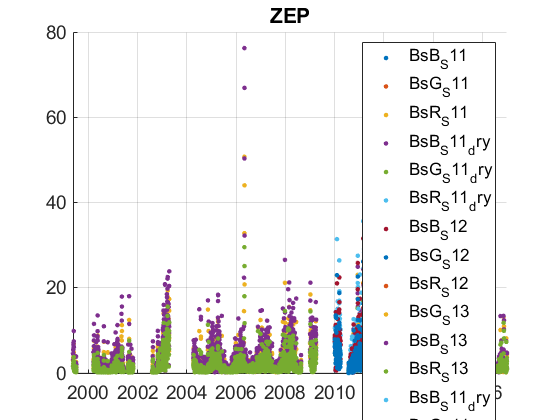

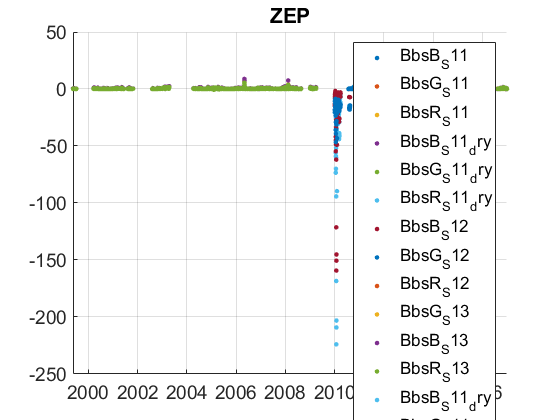

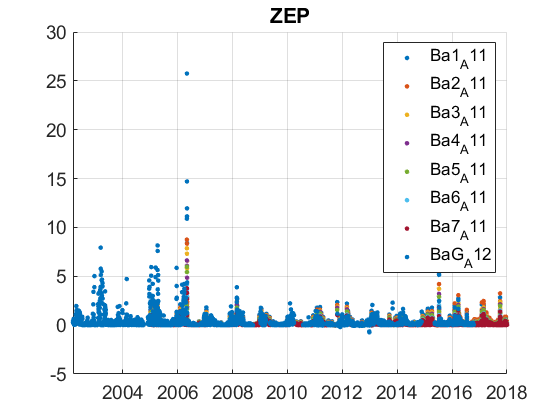

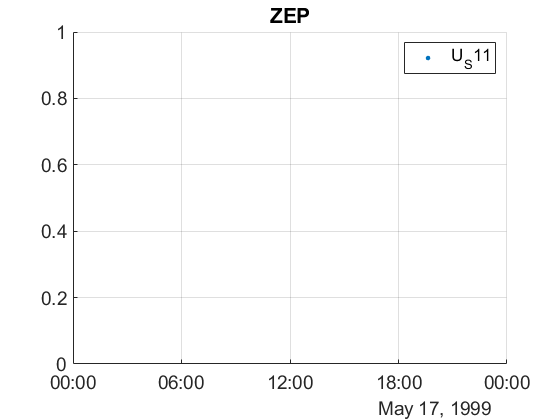

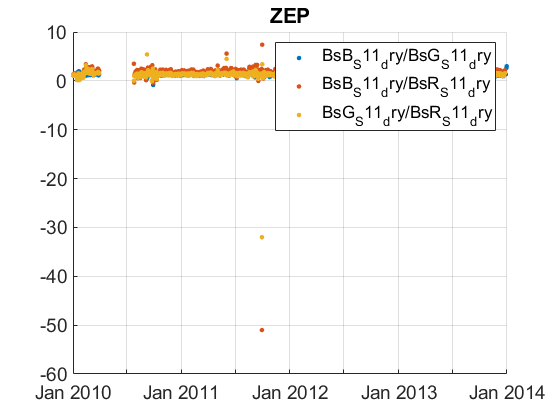

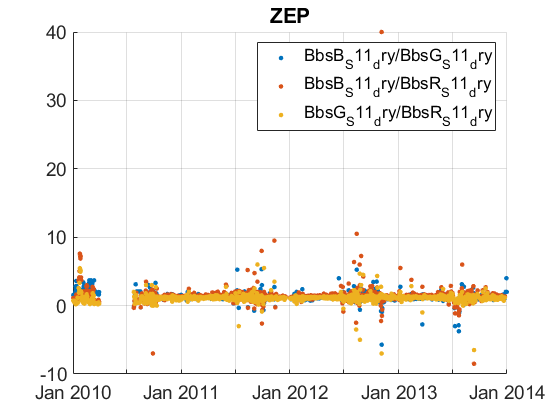

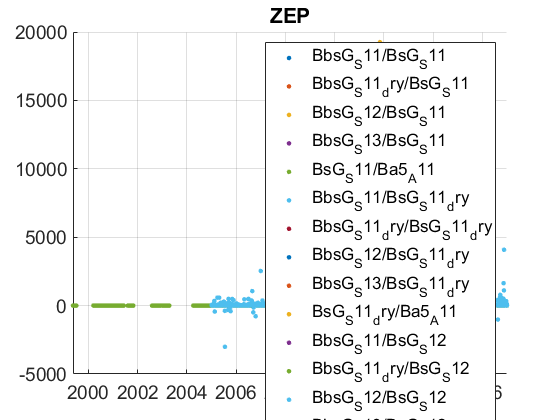

%put the 2011-2012 DATA FROM kOSTAS
p12=timerange('2011-01-01','2013-01-01');
ZEP_rd2.Ba1_A11(p12)=AE_x_d.Abs370;
ZEP_rd2.Ba2_A11(p12)=AE_x_d.Abs470;
ZEP_rd2.Ba3_A11(p12)=AE_x_d.Abs520;
ZEP_rd2.Ba4_A11(p12)=AE_x_d.Abs590;
ZEP_rd2.Ba5_A11(p12)=AE_x_d.Abs660;
ZEP_rd2.Ba6_A11(p12)=AE_x_d.Abs880;
ZEP_rd2.Ba7_A11(p12)=AE_x_d.Abs950;

plotFigControl(ZEP_rd2,ZEP_st.name);

lambdaSC=[450;550;700]*ones(1,4);
lambdaAE=[467;530;660]*ones(1,4);
lambdaAE7=[370 470 520 590 660 880 950];
ZEP_cal=compute_exp_SSA(ZEP_rd2,lambdaSC, lambdaAE);

SCexclus = 50

ans = 258

ans = 3166

ans = 0

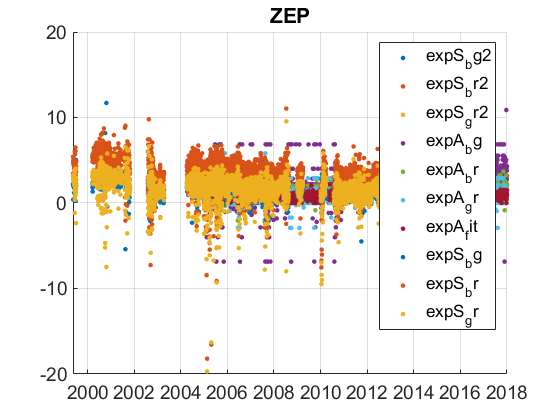

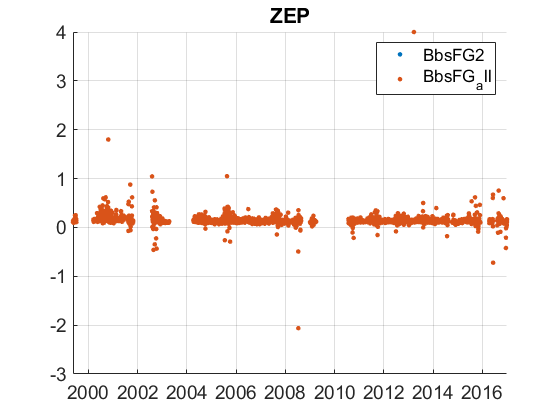

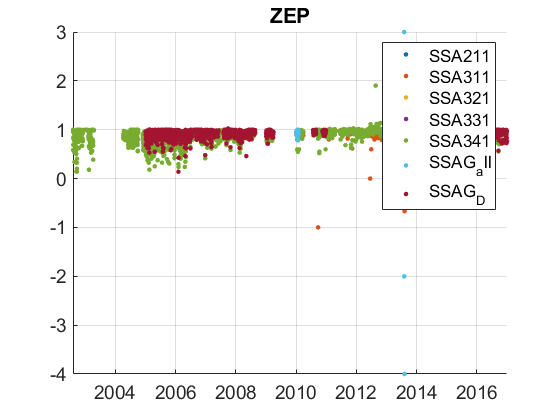

ZEP_cal.SSAG_all=ZEP_rd2.BsG_S13./(ZEP_rd2.BsG_S13+ZEP_rd2.Ba3_A11);
ZEP_cal.SSAG_D=ZEP_rd2.BsG_S12./(ZEP_rd2.BsG_S12+ZEP_rd2.Ba3_A11);
ZEP_cal.BbsFG_all=ZEP_rd2.BbsG_S13./ZEP_rd2.BsG_S13;

ZEP_cal.expS_bg=real(-log(ZEP_rd2.BsB_S13./ZEP_rd2.BsG_S13)/log(lambdaSC(1)/lambdaSC(2)));
ZEP_cal.expS_br=real(-log(ZEP_rd2.BsB_S13./ZEP_rd2.BsR_S13)/log(lambdaSC(1)/lambdaSC(2)));
ZEP_cal.expS_gr=real(-log(ZEP_rd2.BsG_S13./ZEP_rd2.BsR_S13)/log(lambdaSC(1)/lambdaSC(2)));

plotFigControl_cal(ZEP_cal, ZEP_st.name);

% % ZEP_cal3=compute_exp_SSA(ZEP_rd2,lambdaSC, lambdaAE);

SCexclus = 50

ans = 258

ans = 3166

ans = 0

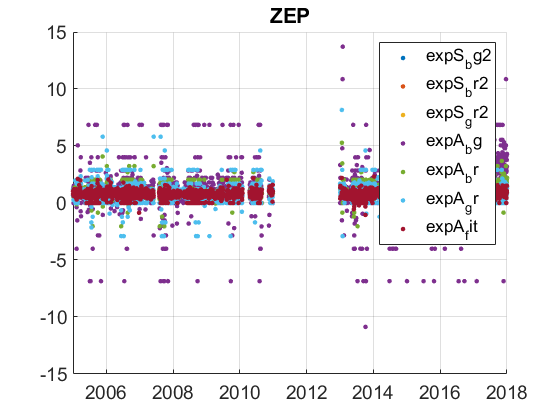

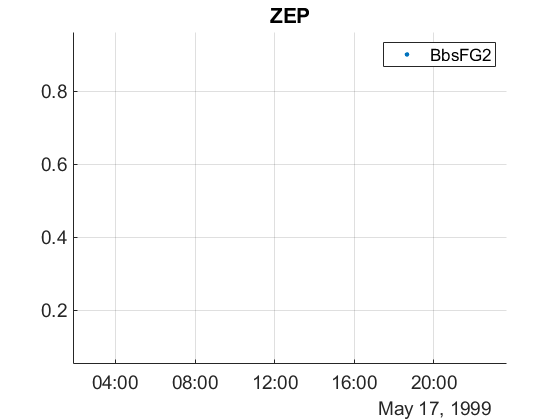

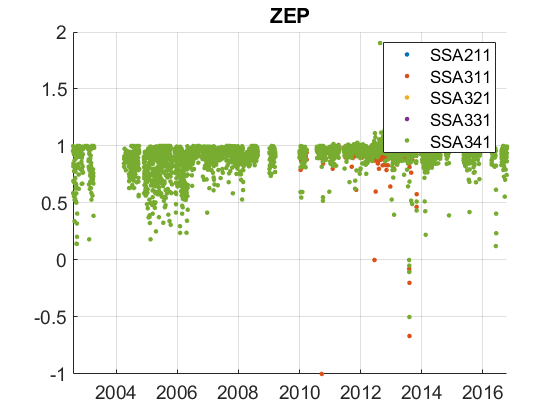

% % plotFigControl_cal(ZEP_cal3, ZEP_st.name);

ZEP_tr=ZEP_rd2; 
ZEP_tr.y=year(ZEP_tr.Time);
% ABS begin at the beginning of a year: 2005 end in 2017
% if Betsy scat: no trend
% if Dominic scat: could begin in 2001, but there is hole in 2002 + calibration problem in 2003 
% --> begin in 2005 to be secure), end in 2016
P=timerange('2005-01-01','2018-01-01');
ZEP_tr=ZEP_tr(P,:);

% problem with U> 290, don't use U and dry
% %use only AE31 
names=fieldnames(ZEP_tr);
c= startsWith(names,["X";"BaG_A12";"U";"P_";"T_"]) | endsWith(names,'dry');
N=names(c);
for i=1:length(N)
    ZEP_tr.(N{i})=[];
end
%use Dominic data
ZEP_tr.BsB_S11=[];
ZEP_tr.BsG_S11=[];
ZEP_tr.BsR_S11=[];
ZEP_tr.BbsB_S11=[];
ZEP_tr.BbsG_S11=[];
ZEP_tr.BbsR_S11=[];
% try to use dominic + ebas in 2013 and 2010
ZEP_tr.BsB_S12=[];
ZEP_tr.BsG_S12=[];
ZEP_tr.BsR_S12=[];
ZEP_tr.BbsB_S12=[];
ZEP_tr.BbsG_S12=[];
ZEP_tr.BbsR_S12=[];

%use AE31 and not PSAP:
%ZEP_tr.BaG_A12=[];

ZEP_cal2=compute_exp_SSA(ZEP_tr,lambdaSC, lambdaAE);

SCexclus = 315

ans = 71

ans = 468

ans = 0

ZEP_cal2.SSAG_all=ZEP_tr.BsG_S13./(ZEP_tr.BsG_S13+ZEP_tr.Ba3_A11);
%ZEP_cal2.SSAG_D=ZEP_tr.BsG_S12./(ZEP_tr.BsG_S12+ZEP_tr.Ba3_A11);
ZEP_cal2.BbsFG_all=ZEP_tr.BbsG_S13./ZEP_tr.BsG_S13;

ZEP_cal2.expS_bg=real(-log(ZEP_tr.BsB_S13./ZEP_tr.BsG_S13)/log(lambdaSC(1)/lambdaSC(2)));
ZEP_cal2.expS_br=real(-log(ZEP_tr.BsB_S13./ZEP_tr.BsR_S13)/log(lambdaSC(1)/lambdaSC(2)));
ZEP_cal2.expS_gr=real(-log(ZEP_tr.BsG_S13./ZEP_tr.BsR_S13)/log(lambdaSC(1)/lambdaSC(2)));

ZEP_tr=outerjoin(ZEP_tr, ZEP_cal2);
%compute trend only on Ba3 and fit

ZEP_tr.Ba1_A11=[];
ZEP_tr.Ba2_A11=[];
ZEP_tr.Ba4_A11=[];
ZEP_tr.Ba5_A11=[];
ZEP_tr.Ba6_A11=[];
ZEP_tr.Ba7_A11=[];

ZEP_tr.expA_bg=[];
ZEP_tr.expA_br=[];
ZEP_tr.expA_gr=[];

%compute trend on G and expS_bg:
ZEP_tr.BsB_S13=[];
ZEP_tr.BsR_S13=[];
ZEP_tr.BbsB_S13=[];
ZEP_tr.BbsR_S13=[];

ZEP_tr.expS_br=[];
ZEP_tr.expS_gr=[];

ZEP_result=all_trend_STN(ZEP_tr,ZEP_st);

ZEP_result_D=ZEP_result;